# Sagittal Bounding Model

clear; close all; clc;


## Constant Parameters

% System Parameters
m = 33;             % [kg] mass of hip
I = 2.9;            % [kg m^2]
r_1 = 0.4;          % [m] thigh length
r_2 = 0.3;          % [m] shank length
body_length = 0.7;  % [m]

% Environment Parameters
g = 9.80665;                               % [m/s^2] gravitational constant
contact_stiffness = 400/0.001;              % Approximated at weight (N) / desired displacement (m)
contact_damping = contact_stiffness/10;     % Tuned based on contact stiffness value
mu_s = 0.9;                                   % Static friction coefficient: Around that of rubber-asphalt (actually made it so slipping was impossible)
mu_k_vals = [0.1,0.3,0.6];                                 % Kinetic friction coefficient: Lower than the static coefficient
mu_vth = 0.1;                               % Friction velocity threshold (m/s)

% Animation Parameters
dis = 3;            % [m] distance of travel for animation
start = 1;          % [] animation data start point


## Initial Conditions

theta_1i = deg2rad(-101.5172); %-34.88                                                 % [rad] intial theta 1 angle
theta_2i = deg2rad(80.4059);   %-80.4059                                               % [rad] intial theta 2 angle
th_dot_i = -1.15;                                                               % [rad/s] initial angular velocity of the mass
th_i = -0.07;                                                               % [rad] initial mass angle
x_hip = -r_1*cos(theta_1i) - r_2*cos(theta_1i + theta_2i);                  % [m] initial x hip position
y_hip = -r_1*sin(theta_1i) - r_2*sin(theta_1i + theta_2i);                  % [m] initial y hip position

x_i = -0.2 - (body_length/2)*cos(th_i);
y_i = 0.5 -(body_length/2)*sin(th_i); 
x_dot_i = 4;                                                                % [m/s] initial center of mass horizontal velocity
y_dot_i = 0;                                                                % [m/s] initial center of mass vertical velocity
v = 4;

%potential back stance ICs
theta_1i_B = deg2rad(-34.88);
theta_2i_B = deg2rad(-80.4059);
%theta_1i_B = deg2rad(-78.5);
%theta_2i_B = deg2rad(-80.4);


## Gait timing

l = 0.4;                            % [m] stride length
T_swing = 0.22;                     % [s] swing time
T_stance = l/v;                     % [s] stance time
T = T_swing + T_stance;             % [s] Total gait time
amp_y = m*g*T*pi()/(4*T_stance);   % [N] Vertical force profile amplitude
amp_x = 50;                         % [N] Suggested from MIT paper (50)
time = 0.12;                       % [s] Simulation time
T_air = (T_swing - T_stance)/2;     % [s] Time in the air


## Impedance Control Gains

K = 500;    % Stiffness
B = 150;    % Damping
C = 30;
D = 15;
normal = zeros(250000,length(mu_k_vals));
friction = zeros(250000,length(mu_k_vals));
sim_time = zeros(250000,length(mu_k_vals));

## Simulation

u = [g,m,I,r_1,r_2,T_stance,T_air,amp_y,amp_x];
for i = 1:length(mu_k_vals)
    mu_k = mu_k_vals(i);
    SSout = sim('Friction.slx');
    
    [A,~,idx]=unique(SSout.slip,'stable');
    n=accumarray(idx(:),1);
    slipery=A(find(n~=1));
    
    slip(i) = slipery(2);
    
    [A,~,idx]=unique(SSout.slip_time,'stable');
    n=accumarray(idx(:),1);
    slipery=A(find(n~=1));
    
    slip_time(i) = slipery(2);
    
    normal(1:length(SSout.tout),i) = SSout.normal;
    friction(1:length(SSout.tout),i) = SSout.friction;
    sim_time(1:length(SSout.tout),i) = SSout.tout;
end

## Plots

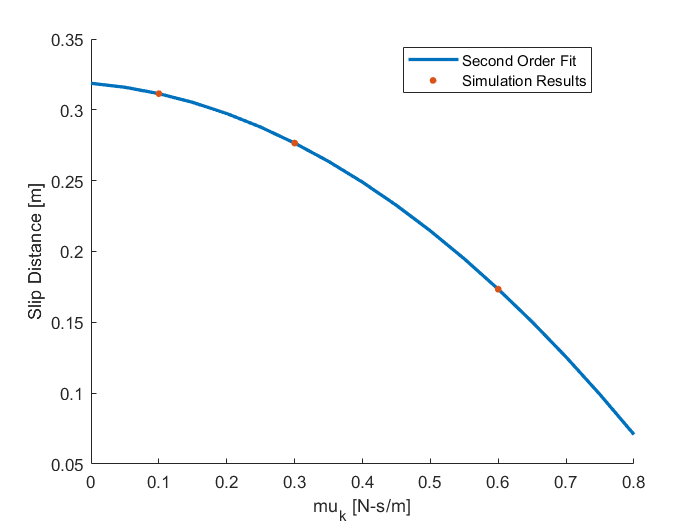

p = polyfit(mu_k_vals,slip,2);
mu = 0:0.05:0.8;
slip_cont = p(1)*(mu.^2) + p(2)*mu + p(3);
figure;
hold on;
plot(mu,slip_cont,"LineWidth",2);
plot(mu_k_vals,slip,"LineStyle","none","Marker",".","MarkerSize",14);
xlabel("mu_k [N-s/m]");
ylabel("Slip Distance [m]");
legend("Second Order Fit", "Simulation Results", "Location","best");
hold off;

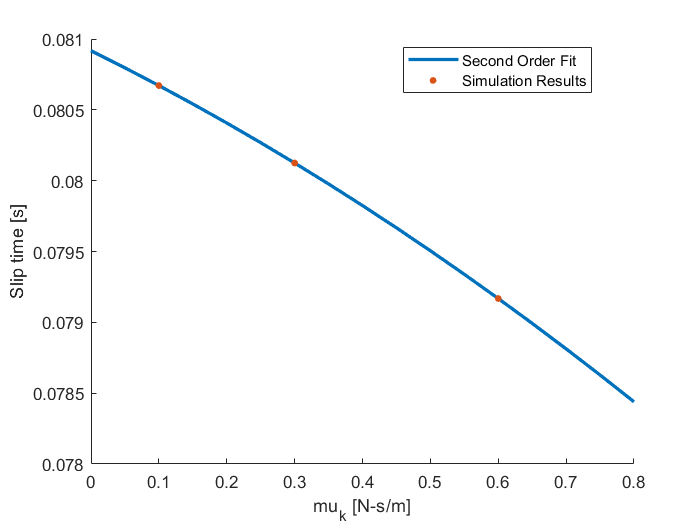


p = polyfit(mu_k_vals,slip_time,2);
mu = 0:0.05:0.8;
slip_time_cont = p(1)*(mu.^2) + p(2)*mu + p(3);
figure;
hold on;
plot(mu,slip_time_cont,"LineWidth",2);
plot(mu_k_vals,slip_time,"LineStyle","none","Marker",".","MarkerSize",14);
xlabel("mu_k [N-s/m]");
ylabel("Slip time [s]");
legend("Second Order Fit", "Simulation Results", "Location","best");
hold off;

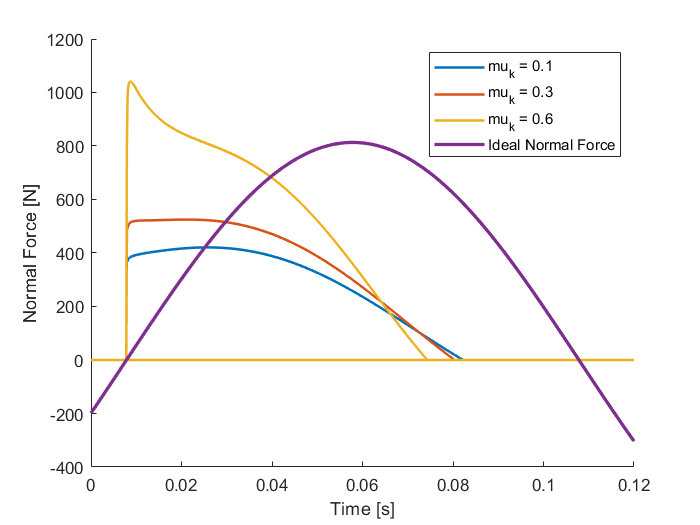


t = 0:0.0005:time;
B_Y = amp_y*sin((pi()/T_stance)*(t-SSout.touch_time(end)));
B_x = amp_x*sin((pi()/T_stance)*(t-SSout.touch_time(end)));
figure;
hold on;
for i = 1:length(mu_k_vals)
    plot(sim_time(:,i),normal(:,i),"LineWidth",1.5);
end
plot(t,B_Y,"LineWidth",2);
xlabel("Time [s]");
ylabel("Normal Force [N]");
legend("mu_k = 0.1","mu_k = 0.3","mu_k = 0.6","Ideal Normal Force");
hold off;

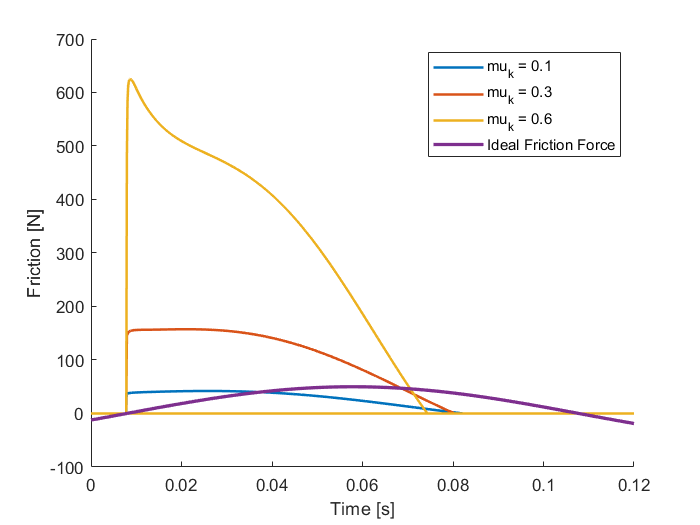


figure;
hold on;
for i = 1:length(mu_k_vals)
    plot(sim_time(:,i),friction(:,i),"LineWidth",1.5);
end
plot(t,B_x,"LineWidth",2);
xlabel("Time [s]");
ylabel("Friction [N]");
legend("mu_k = 0.1","mu_k = 0.3","mu_k = 0.6","Ideal Friction Force");
hold off;